# **MicroGrad Demo**

## Setup

% Add Value, Neuron, Layer, and MLP classes to the MATLAB path
addpath("engine");
addpath("nn");

% Use a fixed seed for reproducibility 
rng(1337);

#### Generate Dataset

Use the `make_moons()` function to create a dataset for binary classification. The function is derived from the scikit Python implementation.

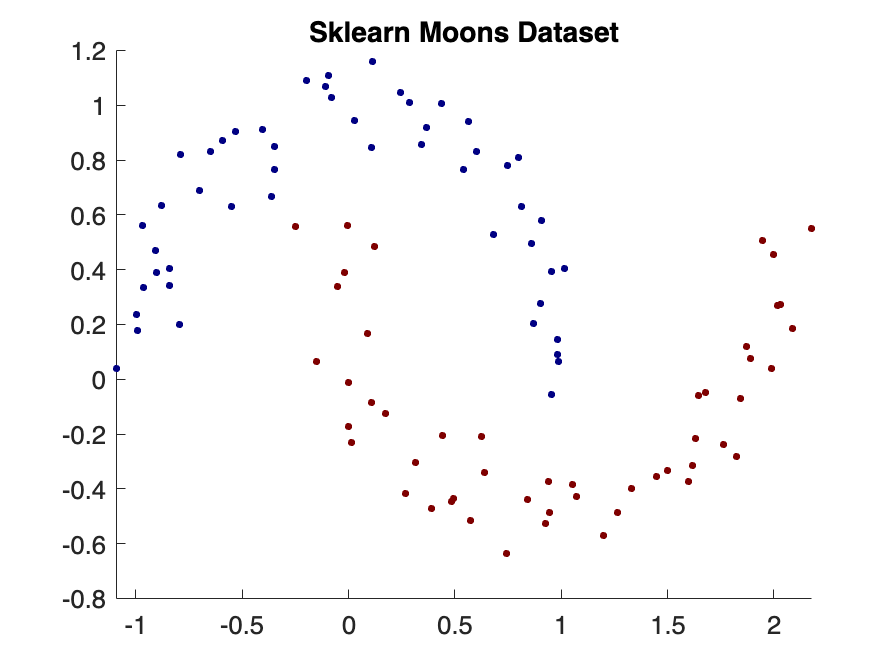

% Make up a dataset
[X, y] = make_moons(n_samples=100, noise=0.1);

y = y*2 - 1; % make y be -1 or 1

% Visualize in 2D
figure();
scatter(X(:, 1), X(:, 2), 20, y, "filled")
colormap("jet");
title("Sklearn Moons Dataset")

% Initialize a model
model = MLP(2, [16, 16, 1]); % 2-layer neural network
display(model);

model =   MLP with properties:

    layers: [3×1 Layer]


fprintf("number of parameters %d\n", length(model.parameters()));

number of parameters 337


#### Visualizing Decision Boundary

We can observe the initial decision boundary that results from our random weights.

The `plot_decision()` function discretizes the xy-plane into a grid, and computes the MLP's decision for each grid point.

function plot_decision(model, X, y)
h = 0.25;
x_min = min(X(:, 1)) - 1;
x_max = max(X(:, 1)) + 1;
y_min = min(X(:, 2)) - 1;
y_max = max(X(:, 2)) + 1;
[xx, yy] = meshgrid(x_min:h:x_max, y_min:h:y_max);
Xmesh = [xx(:), yy(:)];
inputs = arrayfun(@(data) Value(data), Xmesh);
scores = repmat(Value.empty, length(Xmesh), 0);
for idx_point = 1:length(Xmesh)
    point = inputs(idx_point, :);
    scores(idx_point) = model.fire(point');
end
Z = arrayfun(@(s) s.data > 0, scores);
Z = reshape(Z, size(xx));
Z = Z*2 - 1;

figure(); hold on;
contourf(xx, yy, Z, "FaceAlpha", 0.8);
scatter(X(:, 1), X(:, 2), 40, y, "filled");
xlim([min(xx, [], "all"), max(xx, [], "all")]);
ylim([min(yy, [], "all"), max(yy, [], "all")]);
colormap("jet");
end

#### Initial Decision Boundary

This will take several seconds to run, depending on how fast your computer is.

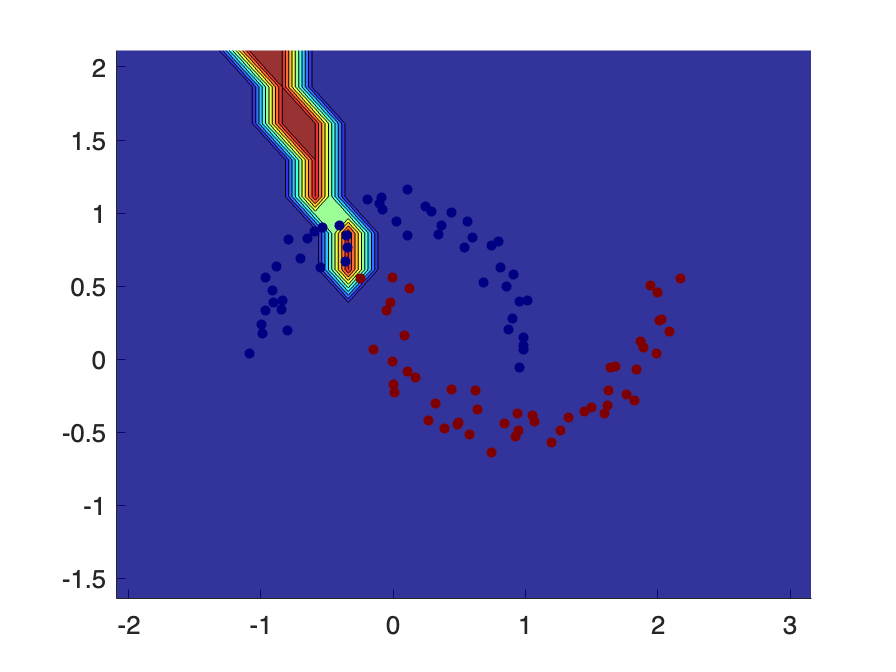

plot_decision(model, X, y);

## Training

#### Loss Function

function [total_loss, acc] = loss(model, X, y, batch_size)

    arguments (Input)
        model (1, 1) MLP
        X (:, 2) double
        y (:, 1) double
        batch_size double {mustBeScalarOrEmpty, mustBeInteger} = []
    end

    arguments (Output)
        total_loss (1, 1) Value
        acc (1, 1) double
    end

    if isempty(batch_size)
        Xb = X;
        yb = y;
        batch_size = length(X);
    else
        ri = randperm(size(X, 1));
        ri = ri(1:batch_size);
        Xb = X(ri);
        yb = y(ri);
    end
    
    % Convert from floats/doubles to Value objects
    inputs = arrayfun(@(data) Value(data), Xb);
    
    scores = repmat(Value(0), batch_size, 1);
    for idx_point = 1:batch_size
        point = inputs(idx_point, :);
        scores(idx_point) = model.fire(point');
    end

    % svm "max-margin" loss
    losses = arrayfun(@(yi, scorei) (1 + -yi*scorei), yb, scores);
    losses = arrayfun(@(loss) loss.relu(), losses); % need to apply ReLU separately since MATLAB doesn't support (1 + -yi*scorei).relu() syntax 
    data_loss = Value.sum(losses) * (1.0 / batch_size);
    % L2 regularization
    alpha = 1e-4;
    reg_loss = alpha * Value.sum(arrayfun(@(p) p * p, model.parameters()));
    total_loss = data_loss + reg_loss;

    % also get accuracy
    accuracy = arrayfun(@(yi, scorei) (yi > 0) == (scorei.data > 0), yb, scores);
    acc = sum(accuracy) / batch_size;
end

#### First Pass

[total_loss, acc] = loss(model, X, y);
display(total_loss);

total_loss =   Value with properties:

                data: 1.6874
                grad: 0
    backward_closure: @Value.plus/backward_closure
                prev: dictionary (Value ⟼ logical) with 2 entries
                  op: "+"


display(acc);

acc = 0.4700

#### Optimization

Run a training loop with 50 iterations. This should take a several minutes to run. Use the stop button to exit early and be able to skip to the next block.

epochs = 50;
accs = zeros(epochs, 1);
for k = 0:(epochs - 1)

    % forward
    [total_loss, acc] = loss(model, X, y);

    % backward
    model.zero_grad();
    total_loss.backward();

    % update (sgd)
    learning_rate = 1.0 - 0.9*k/100;
    params = model.parameters();
    for idx_p = 1:numel(params)
        p = params(idx_p);
        p.data = p.data - learning_rate * p.grad;
    end

    if mod(k, 1) == 0
        fprintf("step %d loss %.4f, accuracy %.1f%%\n", k, total_loss.data, acc * 100);
    end

    accs(k + 1) = acc * 100;

end

step 0 loss 0.1537, accuracy 94.0%
step 1 loss 0.1163, accuracy 95.0%


k = k + 1;

#### Training Accuracy

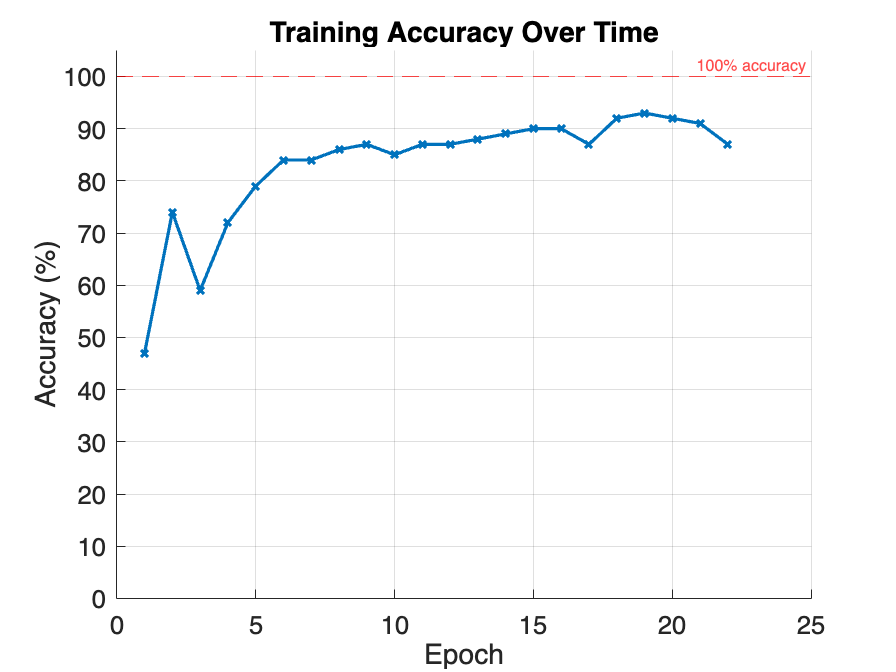

figure(); hold on; grid on;
plot(1:k, accs(1:k), "x-");
yline(100, "r--", "100% accuracy");
xlabel("Epoch");
ylabel("Accuracy (%)");
title("Training Accuracy Over Time");
ylim([0, 105]);

#### Final Decision Boundary

plot_decision(model, X, y);